colobj = roomspec();

resolution = 100;
binary_map = colobj2binary_map(colobj, resolution);

show(binary_map);
view(-90,90);

lidar = rangeSensor("HorizontalAngleResolution", 2*pi/50);

pose = [1 1 deg2rad(45)];
tic
[ranges,angles] = lidar(pose,binary_map);
toc

Elapsed time is 0.010701 seconds.


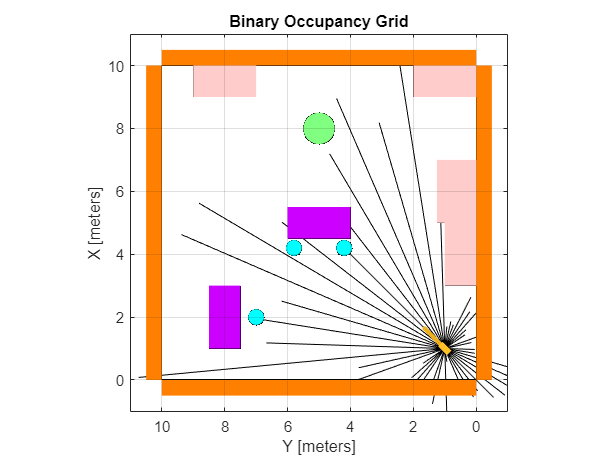

plot_scans(ranges, angles, pose);

robot=robotspec([0.4 0.2 0.2]);
hold on
robotshow(robot,pose);
roomshow(roomspec)
hold off

function plot_scans(ranges, angles, pose)
hold on

for i = 1:length(ranges)
    plot(pose(1)+[0 cos(pose(3)+angles(i))*ranges(i)], pose(2)+[0 sin(pose(3)+angles(i))*ranges(i)], 'k')
    
end

hold off
end